tic; clc; clear; close all;

%% ================= PATHS =================
spec_folder = "C:\Users\parka\OneDrive\Documents\S4_proj\MFC_4\ESC-50\Saved_MelSpectrograms";
metaFile     = "C:\Users\parka\OneDrive\Documents\S4_proj\MFC_4\ESC-50\meta\esc50.csv";

meta = readtable(metaFile);

%% ================= PARAMETERS =================
numClasses = 50;
samplesPerClass = 40;

numBands  = 32;
numFrames = 64;

d = numBands * numFrames;        % 2048
totalSamples = numClasses * samplesPerClass;  % 2000

%% ================= STORAGE =================
X = zeros(d, totalSamples);
col = 1;

%% ================= MAIN LOOP =================
for classID = 0

    fprintf("Processing class %d\n", classID);

    % ---- get all files of this class ----
    idx = meta.target == classID;
    classFiles = meta.filename(idx);

    % safety check
    assert(length(classFiles) >= samplesPerClass, ...
        "Not enough samples for class %d", classID);

    % ---- take first 40 samples ----
    for j = 1

        fname = classFiles{j};
        matName = erase(fname, ".wav") + ".mat";

        load(fullfile(spec_folder, matName)); % loads melSpec
    

        % ---- resize ----

        S = imresize(melSpec, [numBands numFrames]);

        % ---- normalize ----
        S = (S - mean(S(:))) / (std(S(:)) + 1e-6);
        S = S / max(abs(S(:)));

        % ---- store ----
        X(:, col) = S(:)
        col = col + 1;
    end
end

Processing class 0


X =    -0.0872         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0872         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     


%% ================= FINAL CHECK =================
disp("Final matrix sizes:");

Final matrix sizes:


disp(size(X));   % 2048 x 2000

        2048        2000




fprintf("ESC-50 matrix construction DONE\n");

ESC-50 matrix construction DONE


toc

Elapsed time is 0.096446 seconds.


Y = kron(1:50,ones(1,40));
Y1h = dummyvar(Y)';
min(X(:))

ans = -0.1321

max(X(:))

ans = 1

mean(X(:))

ans = -1.4299e-19

std(X(:))

ans = 0.0063

Xtrain50=zeros(numBands*numFrames,1000);
Ytrain50=zeros(50,1000);
Xtest50=zeros(numBands*numFrames,1000);
Ytest50=zeros(50,1000);

for i=1:numClasses
    Xtrain50(:,(i-1)*20+1:(i-1)*20+20) = X(:,(i-1)*40+1:(i-1)*40+20);
    Ytrain50(:,(i-1)*20+1:(i-1)*20+20) = Y1h(:,(i-1)*40+1:(i-1)*40+20);

    Xtest50(:,(i-1)*20+1:(i-1)*20+20)  = X(:,(i-1)*40+21:(i-1)*40+40);
    Ytest50(:,(i-1)*20+1:(i-1)*20+20)  = Y1h(:,(i-1)*40+21:(i-1)*40+40);
end
[~,trainlabels]=max(Ytrain50,[],1);
[~,testlabels]=max(Ytest50,[],1);

max(Ytest50,[],1)

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


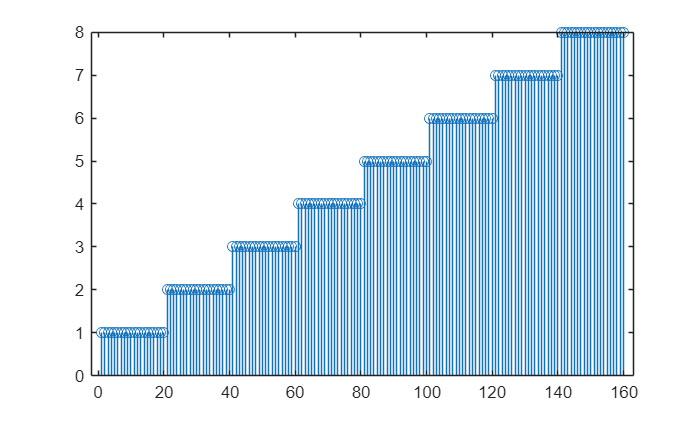

stem(testlabels(1:160))

% Checking no points in each class for training
np = 0;
for i=1:50
    np = np + sum(trainlabels==i);
    fprintf(" class : %i no: data : %i\n",i,sum(trainlabels==i))
end

 class : 1 no: data : 20
 class : 2 no: data : 20
 class : 3 no: data : 20
 class : 4 no: data : 20
 class : 5 no: data : 20
 class : 6 no: data : 20
 class : 7 no: data : 20
 class : 8 no: data : 20
 class : 9 no: data : 20
 class : 10 no: data : 20
 class : 11 no: data : 20
 class : 12 no: data : 20
 class : 13 no: data : 20
 class : 14 no: data : 20
 class : 15 no: data : 20
 class : 16 no: data : 20
 class : 17 no: data : 20
 class : 18 no: data : 20
 class : 19 no: data : 20
 class : 20 no: data : 20
 class : 21 no: data : 20
 class : 22 no: data : 20
 class : 23 no: data : 20
 class : 24 no: data : 20
 class : 25 no: data : 20
 class : 26 no: data : 20
 class : 27 no: data : 20
 class : 28 no: data : 20
 class : 29 no: data : 20
 class : 30 no: data : 20
 class : 31 no: data : 20
 class : 32 no: data : 20
 class : 33 no: data : 20
 class : 34 no: data : 20
 class : 35 no: data : 20
 class : 36 no: data : 20
 class : 37 no: data : 20
 class : 38 no: data : 20
 class : 39 no: data 

np

np = 1000

% Checking no points in each class for testing
np = 0;
for i=1:50
    np = np + sum(testlabels==i);
    fprintf(" class : %i no: data : %i\n",i,sum(testlabels==i))
end

 class : 1 no: data : 20
 class : 2 no: data : 20
 class : 3 no: data : 20
 class : 4 no: data : 20
 class : 5 no: data : 20
 class : 6 no: data : 20
 class : 7 no: data : 20
 class : 8 no: data : 20
 class : 9 no: data : 20
 class : 10 no: data : 20
 class : 11 no: data : 20
 class : 12 no: data : 20
 class : 13 no: data : 20
 class : 14 no: data : 20
 class : 15 no: data : 20
 class : 16 no: data : 20
 class : 17 no: data : 20
 class : 18 no: data : 20
 class : 19 no: data : 20
 class : 20 no: data : 20
 class : 21 no: data : 20
 class : 22 no: data : 20
 class : 23 no: data : 20
 class : 24 no: data : 20
 class : 25 no: data : 20
 class : 26 no: data : 20
 class : 27 no: data : 20
 class : 28 no: data : 20
 class : 29 no: data : 20
 class : 30 no: data : 20
 class : 31 no: data : 20
 class : 32 no: data : 20
 class : 33 no: data : 20
 class : 34 no: data : 20
 class : 35 no: data : 20
 class : 36 no: data : 20
 class : 37 no: data : 20
 class : 38 no: data : 20
 class : 39 no: data 

np

np = 1000

rng(100);

%% ================= BiPIL NETWORK =================

phi     = @(x) cos(x);
phi_inv = @(x) acos(min(max(x,-1),1)); % make X input between -1 and 1 because cos is defined from -1 to 1

W1=2*rand(128,d)-1;
W2=2*rand(64,128)-1;
W3=2*rand(32,64)-1;

%%Forward 
H1s=W1*Xtrain50;
H1=phi(H1s);
H2s=W2*H1;
H2=phi(H2s);
H3s=W3*H2;
H3=phi(H3s);
Wo=Ytrain50*pinv(H3);
ypred1=Wo*H3;
[~, pred_labels1] = max(ypred1, [], 1);

fprintf("Training Accuracy before backward pseudo inv: %.2f %%\n",sum(pred_labels1 == trainlabels)*100/1000);

Training Accuracy before backward pseudo inv: 2.10 %



%%Backward
H3_b=pinv(Wo)*Ytrain50;
H3s_b=phi_inv(H3_b);
H2_b=pinv(W3)*H3s_b;
H2s_b=phi_inv(H2_b);
H1_b=pinv(W2)*H2s_b;
H1s_b=phi_inv(H1_b);

%%Forward
W1_f=H1s_b*pinv(Xtrain50);
H1=phi(W1_f*Xtrain50);
W2_f=H2s_b*pinv(H1);
H2=phi(W2_f*H1);
W3_f=H3s_b*pinv(H2);
H3=phi(W3_f*H2);
Wo=Ytrain50*pinv(H3);
ypred=Wo*H3;

%% TRAIN ACC
[~, pred_labels] = max(ypred, [], 1);

fprintf("Training Accuracy: %.2f %%\n",sum(pred_labels == trainlabels)*100/1000);

Training Accuracy: 2.10 %




%% ================= TEST ACCURACY =================

H1_test = phi(W1_f * Xtest50);
H2_test = phi(W2_f * H1_test);
H3_test = phi(W3_f * H2_test);
ypred_test = Wo * H3_test;
[~,pred_test_labels] = max(ypred_test, [], 1);
tabulate(pred_test_labels)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3        0      0.00%
      4        0      0.00%
      5        0      0.00%
      6        0      0.00%
      7        0      0.00%
      8        0      0.00%
      9        0      0.00%
     10        0      0.00%
     11        0      0.00%
     12        0      0.00%
     13        0      0.00%
     14        0      0.00%
     15        0      0.00%
     16        0      0.00%
     17        0      0.00%
     18        0      0.00%
     19        0      0.00%
     20        0      0.00%
     21        0      0.00%
     22        0      0.00%
     23        0      0.00%
     24        0      0.00%
     25        0      0.00%
     26     1000    100.00%


fprintf("Test Accuracy: %.2f %%\n",sum(pred_test_labels == testlabels)*100/length(testlabels));

Test Accuracy: 2.00 %
